# Evaluación 

A01731921

En esta actividad se implementa el código requerido para generar las siguientes trayectorias a partir del tiempo y de las velocidades angulares y lineales en un plano 2D, según corresponda. En mi caso es mi nombre abreviado: **DANI **

%Limpieza de pantalla
clear all
close all
clc

**Se declara el tiempo de ejecución**

tf=34;             % Tiempo de simulación en segundos (s) 
% para 8 movimientos
ts=0.1;            % Tiempo de muestreo en segundos (s)
t=0:ts:tf;         % Vector de tiempo
N= length(t);      % Muestras

**Se declaran las condiciones iniciales a tomar en cuenta**

%Inicializamos las variables que se van a emplear
x1= zeros (1, N+1);       % Posición (X) en el centro del eje que une 
% las ruedas en metros (m)
y1= zeros (1, N+1);       % Posición (Y) en el centro del eje que une 
% las ruedas en metros (m)
phi= zeros (1, N+1);      % Orientación del robot en radiaanes (rad)

%Damos valores a nuestro punto inicial de posición y orientación
x1(1)=0;  %Posición inicial eje x
y1(1)=0;  %Posición inicial eje y
phi(1)=0; %Orientación inicial del robot 

**Se declara el punto de control en referencia al robot **

%Inicializamos el punto de control 
hx= zeros (1, N+1);       % Posición en el eje (X) del
% punto de control en metros (m)
hy= zeros (1, N+1);       % Posición en el eje (Y) del 
% punto de control en metros (m)

%Igualamos el punto de control con las proyecciones X1 y Y1 por su
%coincidencia
hx(1)= x1(1);       % Posición del punto de control en el eje (X) metros (m)
hy(1)= y1(1);       % Posición del punto de control en el eje (Y) metros (m)

**Se declaran las velocidades de referencia**

La lógica para cada trayectoria se define de la siguiente manera, haciendo un total de 34 pasos:

v = [0*ones(1, 10)      3*ones(1,10)   0*ones(1, 10)         2.24*ones(1, 10)  0*ones(1, 10)     1*ones(1, 10)  0*ones(1, 10)       2.24*ones(1, 10) 0*ones(1,10)  3*ones(1,10)    0*ones(1,10)       2.9*ones(1,11) 0*ones(1,10)     2.128*ones(1,10) 0*ones(1,10)   1.55*ones(1,10) 0*ones(1,10)    1.55*ones(1,10) 0*ones(1,10)    1.33*ones(1,10) 0*ones(1,10)     0.8*ones(1,10) 0*ones(1,10)     3.2*ones(1,10) 0*ones(1,10)     3.95*ones(1,10) 0*ones(1,10)   3.1*ones(1,10) 0*ones(1,10) 3.1*ones(1,10) 0*ones(1,10)   1.8*ones(1,10) 0*ones(1,10)    3.1*ones(1,11)]; % Velocidad lineal de referencia (m/s)
w = [1.5707*ones(1,10)  0*ones(1, 10) -2.0345*ones(1, 10)    0*ones(1, 10)     -1.12*ones(1, 10)  0*ones(1, 10)  -1.107*ones(1, 10) 0*ones(1, 10)   2.6778*ones(1,10) 0*ones(1,10) 1.295*ones(1,10) 0*ones(1,11)    -2.388*ones(1,10) 0*ones(1,10)     -2.11*ones(1,10) 0*ones(1,10)   pi*ones(1,10) 0*ones(1,10)    -1.14*ones(1,10) 0*ones(1,10)    3.2*pi/8*ones(1,10) 0*ones(1,10) pi/2*ones(1,10) 0*ones(1,10)   -2.55*ones(1,10)   0*ones(1,10)  2.55*ones(1,10) 0*ones(1,10) pi*ones(1,10) 0*ones(1,10)   pi/2*ones(1,10) 0*ones(1,10) pi/2*ones(1,10) 0*ones(1,11)]; % Velocidad angular de referencia (rad/s)

**Se inicia bucle de simulación en el cual se declara el modelo cinemático**

for k=1:N 
    
    %Aplico la integral a la velocidad angular para obtener el angulo
    % "phi" de la orientación
    phi(k+1)=phi(k)+w(k)*ts; % Integral numérica (método de Euler)
    
    xp1=v(k)*cos(phi(k)); 
    yp1=v(k)*sin(phi(k));
 
    %Aplico la integral a la velocidad lineal para obtener las cordenadas
    %"x1" y "y1" de la posición
    x1(k+1)=x1(k)+ ts*xp1; % Integral numérica (método de Euler)
    y1(k+1)=y1(k)+ ts*yp1; % Integral numérica (método de Euler)

    % Posicion del robot con respecto al punto de control
    hx(k+1)=x1(k+1); 
    hy(k+1)=y1(k+1);

end

**Ahora se inicia con la simulación virtual en 3D**

Para esta parte se importan los archivos compartidos por el profesor: MobilePlot.m, MobileRobot.m y Uniciclo.mat que se encuentran en la misma carpeta que este código, esto con el fin de poder graficar el entorno en 3D simultáneamente con este programa.

A continuación se muestran los pasos para la visualización:

**a) Configuracion de escena**

scene=figure;  % Crear figura (Escena)
set(scene,'Color','white'); % Color del fondo de la escena
set(gca,'FontWeight','bold') ;% Negrilla en los ejes y etiquetas
sizeScreen=get(0,'ScreenSize'); % Retorna el tamaño de la pantalla del computador
set(scene,'position',sizeScreen); % Configurar tamaño de la figura
camlight('headlight'); % Luz para la escena
axis equal; % Establece la relación de aspecto para que las unidades de datos 
% sean las mismas en todas las direcciones.
grid on; % Mostrar líneas de cuadrícula en los ejes
box on; % Mostrar contorno de ejes
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)'); % Etiqueta de los eje

view([150 150]); % Orientacion de la figura
axis([-1 12 -1 5 0 2]); % Ingresar limites minimos y maximos en los ejes x y z
% [minX maxX minY maxY minZ maxZ]

**b) Graficar robots en la posicion inicial**

scale = 4;
MobileRobot;
H1=MobilePlot(x1(1),y1(1),phi(1),scale);hold on;

**c) Graficar Trayectorias**

H2=plot3(hx(1),hy(1),0,'r','lineWidth',2);

**d) Bucle de simulacion de movimiento del robot**

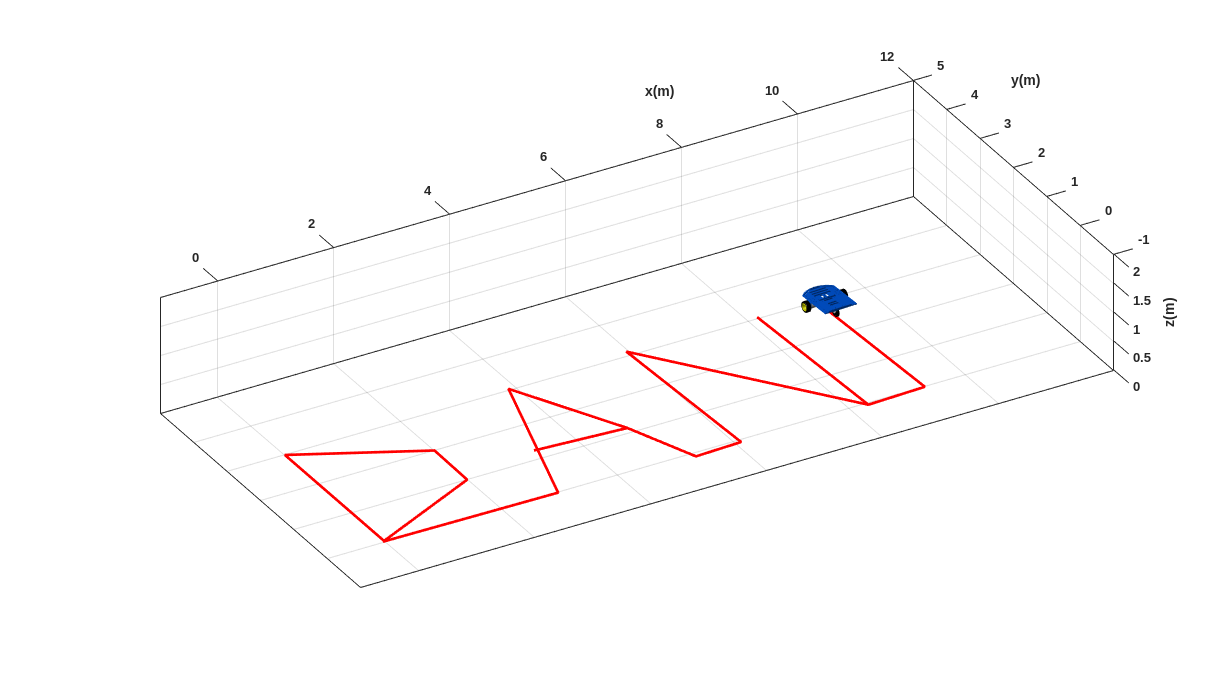

step=1; % pasos para simulacion

for k=1:step:N

    delete(H1);    
    delete(H2);
    
    H1=MobilePlot(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'r','lineWidth',2);
    
    pause(ts);

end

### **Preguntas:**

**a) ¿Cuál fué el o los parámetros que se modifican para obtener una trayectoria recta? ¿Porqué?**

El parámetro que se fue modificando para construir una trayectoria recta fue la velocidad lineal (v)

Esto debido a que estamos modificando la distancia que debe recorrer el robot en cada segmento de cada letra de mi nombre, esta variable contiene un vector con todos los movimientos rectos que debe hacer el robot para cada instante de tiempo, cada tramo se define como "magnitud * ones (1, N)"  lo que hace es crear varios vectores de tamaño 1x10 lleno de unos multiplicados por la magnitud, donde N es la cantidad de muestras entre cada tramo.

**b) ¿Cuál fué el o los parámetros que se modifican para obtener una trayectoria curva? ¿Porqué?**

En este ejercicio por cuestiones de tiempo se decidió emplear únicamente tramos rectos, pero si se hubiera usando una trayectoria curva se tendría que modificar ambos vectores de velocidad lineal y velocidad angular, donde la magnitud sería en radianes y lo importante sería mantener esa cantidad de radianes tanto en v como en w, ya que cada movmiento del robot es una tupla que contiene tanto la velocidad lineal como la angular, si solo se busca avanzar, la magnitud de la velocidad angular sería 0 y si sólo se busca girar, la magnitud de la velocidad lineal sería 0, lo cual es diferente en un tramo curvo ya que involucra ambos vectores.

**c) ¿Cuál fué el o los parámetros que se modifican para obtener un giro? ¿Porqué?**

El parámetro que se fue modificando para realizar un giro fue la velocidad angular (w).

Esto debido a que estamos modificando el ángulo que debe girar el robot al terminar cada segmento de cada letra, esta variable contiene un vector con todos los movimientos de giro que debe hacer el robot para cada instante de tiempo, cada tramo se define como "magnitud * ones (1, N)"  lo que hace es crear varios vectores de tamaño 1x10 lleno de unos multiplicados por la magnitud, la cual en este parámetro esta definido por radianes y donde N es la cantidad de muestras entre cada tramo.

**d) ¿Qué papel desempeña el vector del tiempo en la generación de la trayectoria?**

Porsupuesto va variando el vector final de tiempo para contemplar el tiempo total que le tomará a la simulación completar la trayectoria. En mi caso fui agregando velocidades lineales y angulares poco a poco para debugear y le fui agregando 1 segundo a cada tramo que realizara el robot, haciendo un total de 34 segundos para 34 pasos donde cada paso le toma 1 segundo y de esta manera poder realizar toda la trayectoria. 

**e) ¿Cuáles fueron los parámetros que se ajustaron para obtener las dimensiones de las trayectorias deseadas?**

Las dimensiones que se indicaron para cada letra fueron de alto 3 m y de ancho lo que nosotros consideraramos, por lo que para lograr esta dimensión, como se mencionó previamente, se modificaba la magnitud de cada mini vector  "magnitud * ones (1, N)" que contenia del vector guardado en la variable de velocidad lineal (v), de esta manera se alcanzaba a recorrer por el robot la distancia que cumpla con las dimensiones propuestas.

Esta evaluación nos ayuda a visualizar como funciona la manipulación de un robot modular declarándole la distancia y el ángulo que debe ejecutar para lograr la trayectoria deseada.